# Práctica 3: Grafos.

El objetivo de esta práctica es programar el algoritmo de Kruskal mediante un código de tipo function. Para ello subdividiremos el problema en problemas más pequeños. Para ello recuerda que el objetivo es encontrar un subgrafo **CONEXO** $S=(V(G),C)$ del grafo $G=(V(G),E(G))$ tal que $C$ fuera un conjunto conectador. Para ello, la idea es ir añadiendo aristas al grafo $G'=(V(G),\{\})$ hasta conseguir la propiedad de finalización del algoritmo de Kruskal cumpliendo el resto de pasos.

Recordemos que un grafo $G=(V(G),E(G))$ se podía dar por su matriz de adyacencia $A=Ad(G)$.

## **Problema 1:**

Crea un código del tipo function cuyos inputs sean la matriz de adyacencia de un grafo $G$ y un vértice $e=\{i,j\}\in E(G)$ (el cual se puede representar por la entrada $(i,j)=(j,i)$ de la matriz $A$) y sus outputs sean un array de carácteres especificando si dicha arista pertenecía a un ciclo (no trivial) o no. Nótese que si no existe dicha arista debe dar el mensaje de error correspondiente y que si $A=Ad(G)$ no es una matriz correspondiente a una de adyancencia debe dar error también.

%PRUEBA
A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];
G = graph(A)

G =   graph with properties:

    Edges: [5×2 table]
    Nodes: [5×0 table]


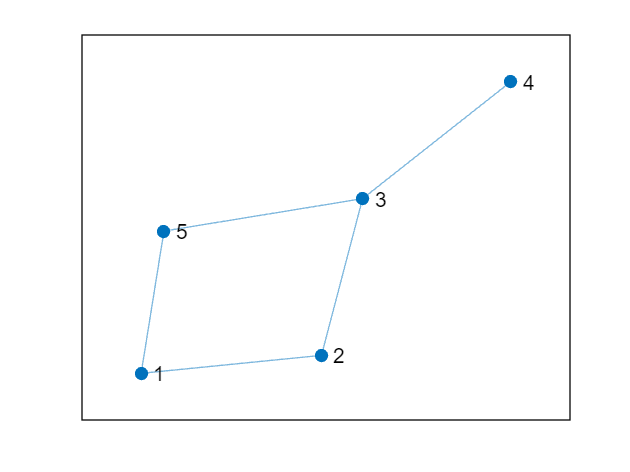

plot(G)

arista = [3, 4];

res = verificaCiclo(A, arista);

disp(res);

Está en un ciclo trivial


% Esta función comprueba si la entrada es una matriz de adyacencia válida

function res = verificaCiclo(m_ady, arista)

    [fil, col] = size(m_ady);
    if fil ~= col || ~isequal(m_ady, m_ady')
        error('Matriz de adyacencia no válida.');
    end
    
    % Vemos si la arista es válida
    if numel(arista) ~= 2 || arista(1) == arista(2) || any(arista < 1) || any(arista > fil) || any(mod(arista, 1) ~= 0)
        error('Error, la arista no puede ser así.');
    end
    
    grafo = m_ady;
    
    % Eliminación de las aristas
    grafo(arista(1), arista(2)) = 0;
    grafo(arista(2), arista(1)) = 0;
    
    % comprobar si es trivial o no
    if perteneceCiclo(grafo, arista(1), arista(2))
        res = 'Está en un ciclo no trivial';
    else
        res = 'Está en un ciclo trivial';
    end
end

function pertenece = perteneceCiclo(grafo, inicio, objetivo)    
    visto = zeros(1, size(grafo, 1));
    visto(inicio) = 1;
    pertenece = dfs(grafo, inicio, objetivo, visto);
end

function res = dfs(grafo, actual, objetivo, visto)
    vecinos = find(grafo(actual, :));

    for i = 1:length(vecinos)
        vecino = vecinos(i);

        if visto(vecino) == 0
            visto(vecino) = -visto(actual);

            if dfs(grafo, vecino, objetivo, visto)
                res = true;
                return;
            end

        elseif visto(vecino) == visto(actual)
            res = true;
            return;
        end

    end

    res = false;

end

